# Display RGB/CMF 

Github Link: https://github.com/pratheepkumar1/Principles-of-Color-Science/tree/main/Assignment%205%20RGB%20CMF

#### Reading the Dataset

warning('off','all');
lms_dataset = readtable("HW_Opponency_Data.xlsx",Sheet="LMS");
rgb_spd_dataset = readtable("HW_DisplaySPD_Data.xlsx",Sheet="DisplaySPD");
cie_dataset = readtable("HW_DisplaySPD_Data.xlsx",Sheet="CIE 1931");

### Question 1: Compute the LMS values of the display’s three primaries

- Create LMS relative sensitivity matrix

- Create Spectral radiance matrix

- Find the change in wavelength

- Calculate LMS of the display using the equation

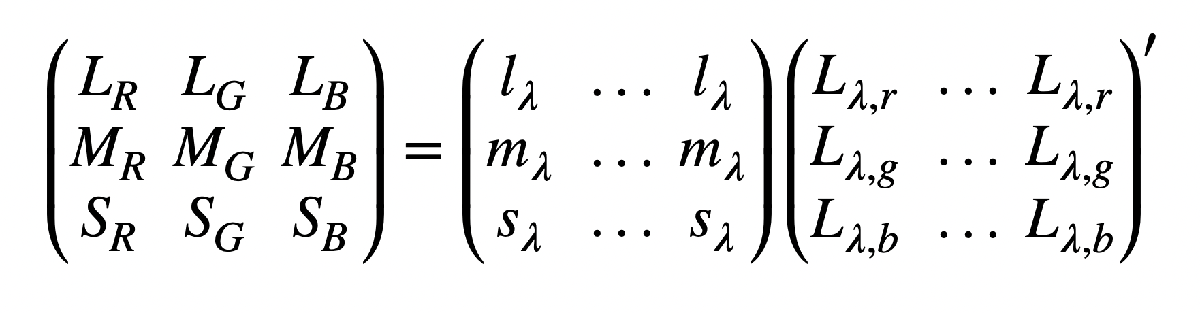

lms_matrix = transpose(lms_dataset{:,[2:4]});

rgb_spd = transpose(rgb_spd_dataset{:,[2:4]});

wavelength = lms_dataset{:,1};
d_lambda = mean(diff(wavelength));

LMS_RGB = calc_LMS_source(lms_matrix,transpose(rgb_spd),d_lambda);

*Generating Table of LMS for the Display (Only for Table Visualisation)*

Table_LMS = array2table(LMS_RGB);
Table_LMS.Properties.VariableNames(1:3) = {'L','M','S'};

### Question 1: Answer

Table_LMS

Table_LMS = 3×3 table
        L           M           S    
    _________    ________    ________

      0.15263      0.3782    0.035192
     0.048391     0.38605    0.052175
    0.0054293    0.035684     0.30713


### Question 2a: Compute the color matching functions (CMFs, also known as r-bar, g-bar, b-bar) of the display’s primaries

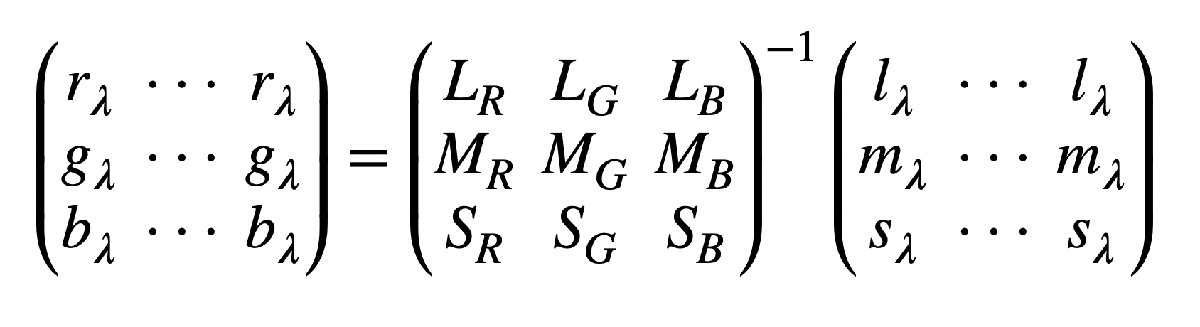

CMF_RGB = LMS_RGB\lms_matrix;

*Generating Table of CMF for the Display (Only for Table Visualisation)*

Table_CMF = array2table(CMF_RGB');
Table_CMF.Properties.VariableNames(1:3) = {'R','G','B'};

### Question 2a: Answer

Table_CMF

Table_CMF = 36×3 table
        R            G            B    
    _________    _________    _________

    0.0038325    -0.003349     0.025067
      0.01538    -0.013447       0.1006
     0.053353    -0.047429      0.35524
      0.13608     -0.12406      0.93964
      0.30318     -0.28278       2.1742
      0.37885     -0.36947       2.9914
      0.33893     -0.36333       3.2922
        0.186     -0.26249       2.9915
    -0.014933     -0.12824       2.6167
     -0.27859     0.070199       2.2401
     -0.56719      0.36033       1.4907
     -0.82537      0.68486      0.83498
      -1.1329       1.1148      0.42286
      -1.5047        1.716      0.13817
      -1.6825       2.3221    -0.085723
      -1.4533       2.6551     -0.19944


### Question 2b: Plotting CMFs versus wavelength

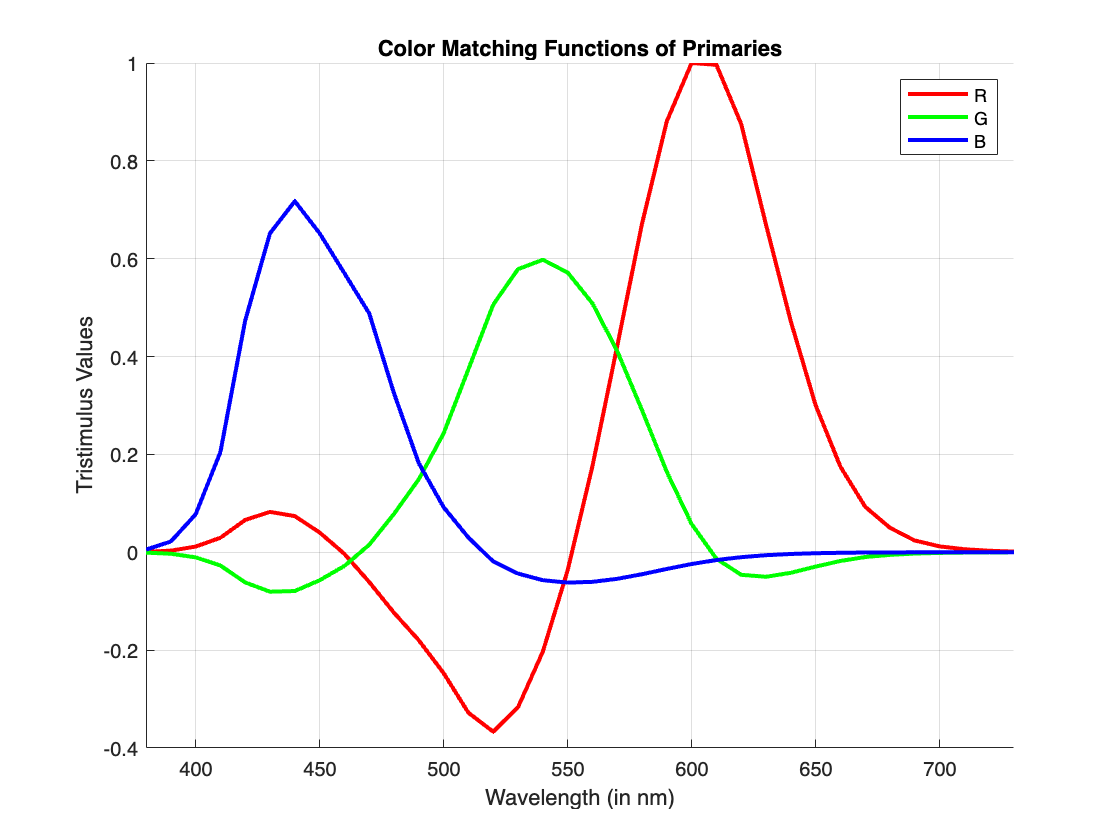

% Rescale the tristimulus values with max value to 1
CMF_RGB_norm = custom_normalization(CMF_RGB);
CMF_RGB_transpose = CMF_RGB_norm';
figure;
colors=['r','g','b'];
labels = ['Red','Green','Blue'];
for i = 1:3
    hold on
    plot(lms_dataset{:,1},CMF_RGB_transpose(:,i), ...
        "LineWidth",2,"Color",colors(i))
end
grid on
xlabel('Wavelength (in nm)')
ylabel('Tristimulus Values')
xlim([380 730])
legend('R','G','B');
title('Color Matching Functions of Primaries')
hold off

### Question 3: Comparing the book's Fig 4.14 (p 56) to our plot (right side)      

Compare your plot to the book’s Fig 4.14 (p 56). What differences do you observe, and why do you think they differ?

### 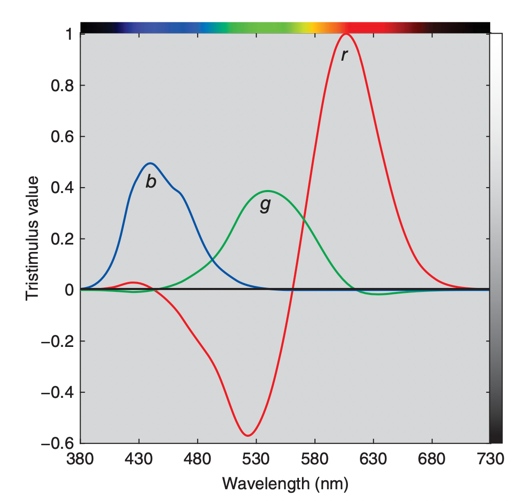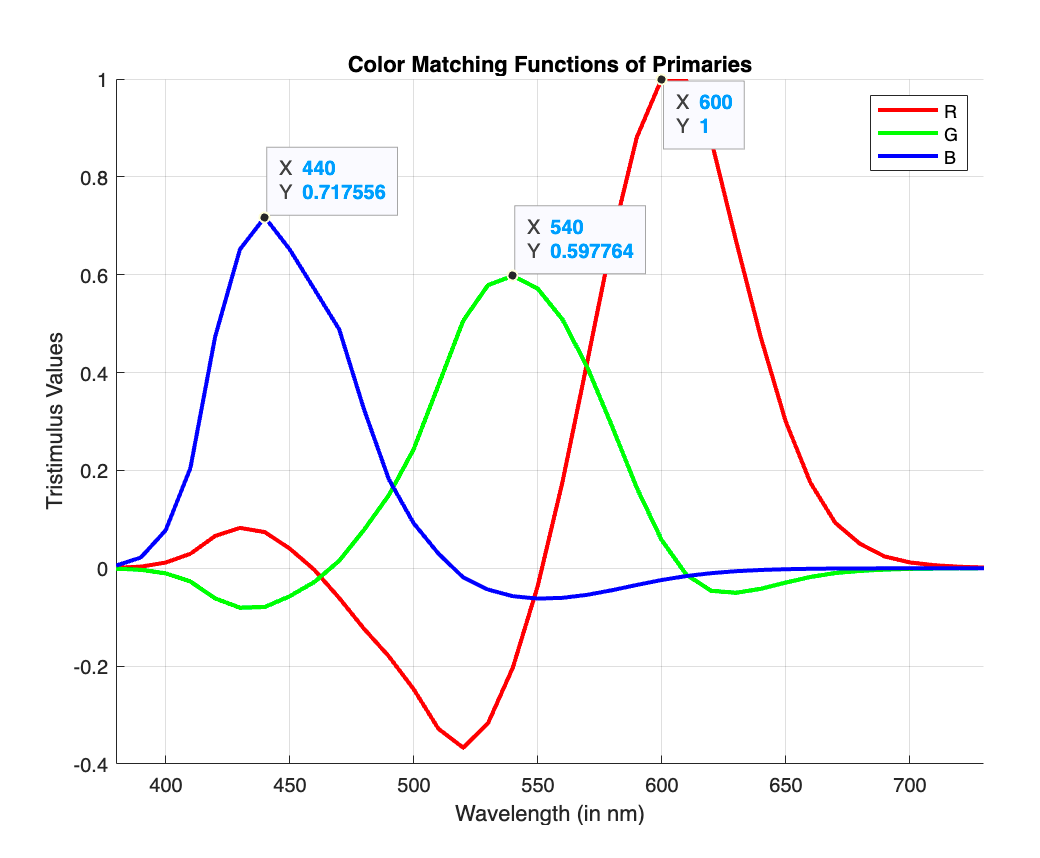

The result of the color-matching function for a display’s R, G, and B primaries are slightly different from figure 4.14. In the book's example, more amount of red is added in the fixed field for color matching and blue is almost not added in the fixed field. Whereas, in our computed plot for the display, more amount of blue light is added in the fixed field for color matching and is represented as negative value in the graph. This is because different primaries selected for LCD displays when compared to the 6 light bulb experiment. For the experiment, primaries were selected at 435.8, 546.1, 600nm. Whereas, in this dataset for the LCD displays,  primaries were selected at 440nm, 540nm and 600nm,

### Question 4: 3x3 matrix to linearly transform the computedCMFs to approximate the CIE 1931 standard colorimetric observer				

- Computing 3x3 matrix (M_function) using the following equation

(x_bar, y_bar, z_bar) = RGB(matrix) x M(matrix)

M(matrix) = RGB(matrix) \ (x_bar, y_bar, z_bar)

CIE_source = cie_dataset{:,2:4};

r_bar_norm = normalize(CMF_RGB(1,:),'norm',1);
g_bar_norm = normalize(CMF_RGB(2,:),'norm',1);
b_bar_norm = normalize(CMF_RGB(3,:),'norm',1);

rgb_bar_norm = [r_bar_norm;g_bar_norm;b_bar_norm];

M_function = rgb_bar_norm'\CIE_source;

### **Question 4: Answer**

M_function

M_function =     9.1919    4.7800    0.3086
    4.4922    9.1800    1.4809
    2.2744    0.8955   11.8684


### **Question 5: **Plot the computed approximation together on the same axes with the actual CIE 1931 functions

% Calculating the approximation using the equation
xyz_bar = rgb_bar_norm'*M_function;

#### Plotting the graph for computed LCD primaries against CIE 1931 standard colorimetric observer.

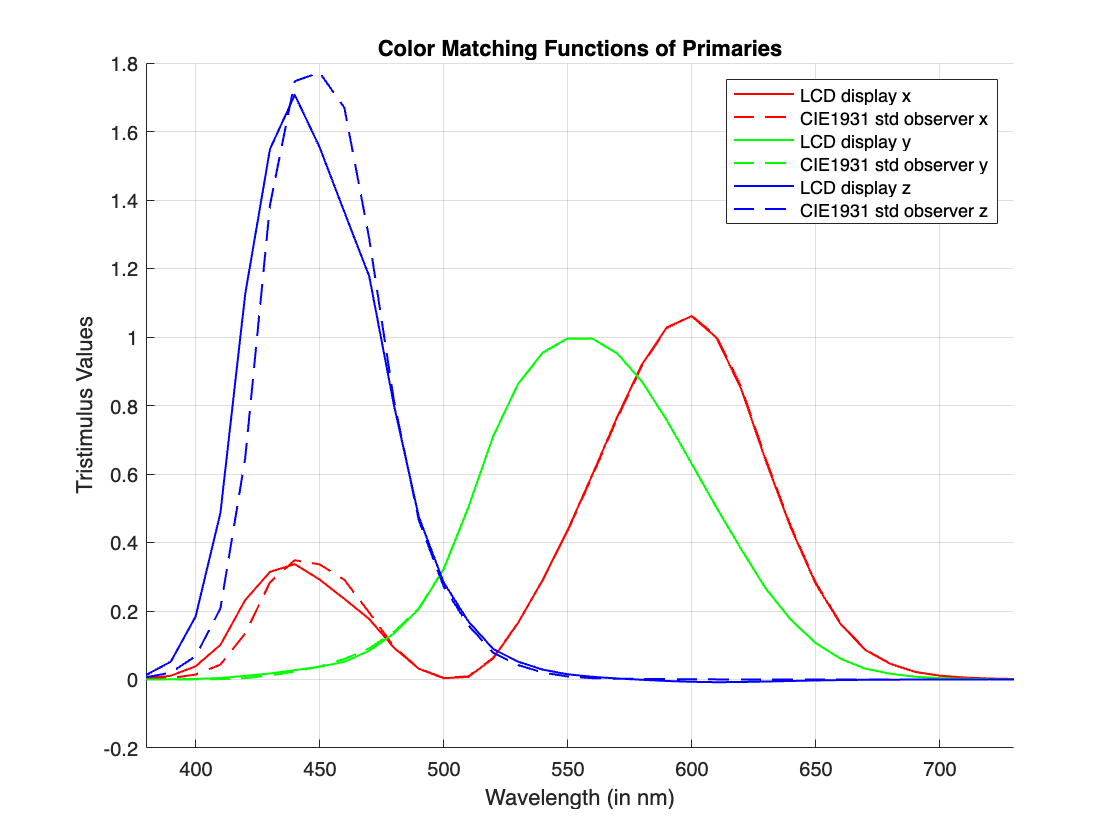

figure;
colors=['r','g','b'];
for i = 1:3
    hold on
    plot(lms_dataset{:,1},xyz_bar(:,i),"LineWidth",1, ...
        "Color",colors(i));
    plot(lms_dataset{:,1},CIE_source(:,i),"LineWidth",1,"Color", ...
        colors(i),"LineStyle","--");
end
grid on
xlabel('Wavelength (in nm)');
ylabel('Tristimulus Values');
xlim([lms_dataset{1,1} lms_dataset{end,1}]);
title('Color Matching Functions of Primaries');
legend('LCD display x','CIE1931 std observer x','LCD display y', ...
    'CIE1931 std observer y','LCD display z','CIE1931 std observer z');
hold off

On comparing the computed LCD primaries against CIE 1931 standard colorimetric observer, as the wavelength increase, especially after 500nm, the tristimulus matches. But for shorter wavelength, LCD display's x_bar and z_bar graphs are slightly shifted left because of the negative value in shorter wavelength for cmf calculation. Whereas y_bar is still the same for both LCD and CIE 1931 because y bar is set to luminance and remains same even after linear transformation. 

### Function used:

*Function to normalize a matrix with its peak value*

function n = custom_normalization(x)
    max_value = max(x, [], 'all');
    n = x/max_value;
end

*Function to calculate LMS of light source*

function T = calc_LMS_source(t,s,d_lambda)
    T = t*s*d_lambda;
end

Function to calculate the approximation of Primaries with respect to CIE 1931 Standard colorimetric observer

function CIE = calc_CIE(M,rgb_bar)
    CIE = M*rgb_bar;
end